The following code solves the heat equation in a rod.

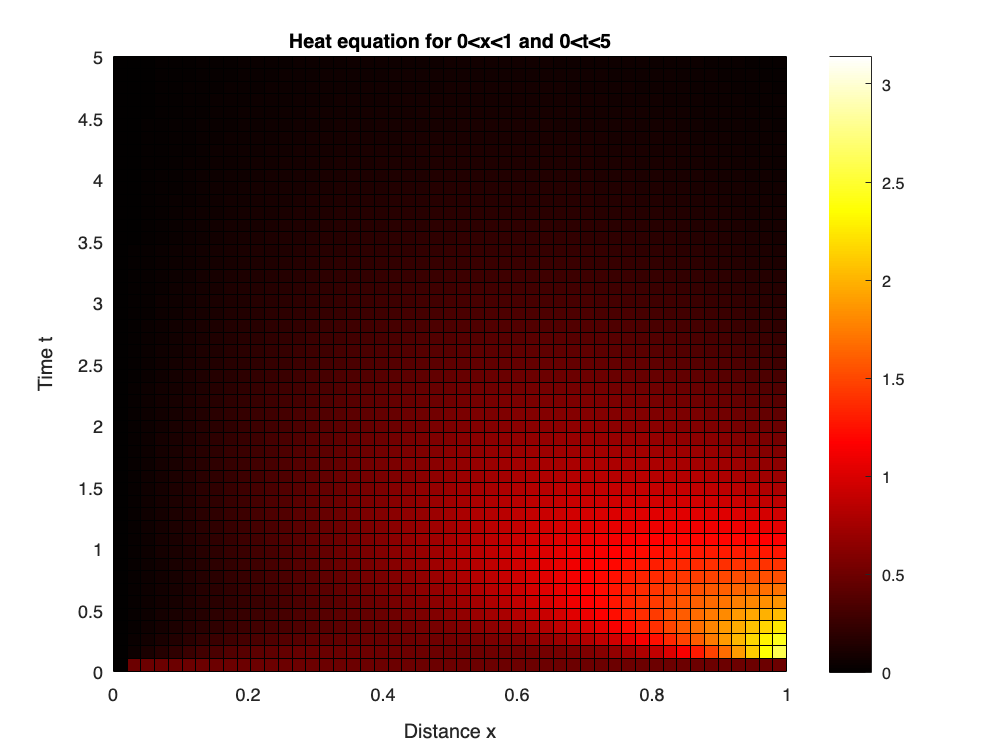

L = 1; % Rod length
x = linspace(0,L,50); % Positions in the rod. Dr. E. used x = linspace(0,L,20);

% Dr. E. used t = [linspace(0,0.05,20),linspace(0.5,5,10)]; % 30 time values, with first 20 between 0 and 0.05
t = linspace(0,5,50);

m = 0;  % Parameter involved in determining the type of differential equation

sol = pdepe(m,@myAwesomePDE,@myInitialCondition,@myBoundaryConditions,x,t);  % @ represents function handles (kind of like their names)


clf   % Clear old figures
colormap hot
pcolor(x,t,sol)
colorbar
xlabel('Distance x')
ylabel('Time t')
title('Heat equation for 0<x<1 and 0<t<5')

## The PDE


$$$c\frac{\partial u}{\partial t} = \alpha\frac{\partial^2 u}{\partial x^2}$$$


This is actually a specific case of $c\frac{\partial u}{\partial t} = x^{-m} \frac{\partial}{\partial x}\left( x^mf \right) + s
$, where $m = 0$, $f = \alpha\frac{\partial u}{\partial x}$, and $s = 0$.

To give these values to `pdepe`, we give it this function whose handle is `@myAwesomePDE` (or anything you want):

function [c,f,s] = myAwesomePDE(x,t,u,dudx)
    c = pi^2;  % Change this to whatever you need
    alpha = 1; % Change this to whatever you need

    f = alpha*dudx;
    s=0;       % Term that can describe a source of heat; not using this
end

We already set $m$ as the first parameter of `pdepe`, so we don't need to worry about it here.

## Initial condition

$u(x, t)$ at time $t = 0$ is some function $g(x)$, which depends only on position $x$ in the rod.

This can be written $$u(x,0) = g(x)$$. In the code, $u(x, 0)$ can be represented as `u0`:

function u0 = myInitialCondition(x)
    u0 = 0.5; % Set u(x,0) to a "boring" function g(x)=0.5
end

## Boundary condition

Our boundary condition looks like$$\begin{cases} u(0,t) = T_0\\ u(L,t) = T_1 \end{cases}$$, where $T_0$ and $T_1$ are specific values depending on the problem.

In the code, we can use `xl` to represent the leftmost x-value ($x = 0$) and `xr` to represent the rightmost x-value ($x = L$, at the end of the rod).

Similarly, $u(0, t)$ (the value of $u$ at `xl`) can be represented as `ul`, while $u(0, t)$ (the value of $u$ at `xl`) can be represented as `ur`.

To give each of these two equations to `pdepe`, we have to put it into the form $p + qf = 0$. ($f$ was defined earlier, but we won't end up needing it.)

How do you do that? 

You can rearrange $$\begin{cases} u(0,t) = T_0\\ u(L,t) = T_1 \end{cases}$$ into $$\begin{cases} \bigl(u(0,t) - T_0\bigr) + 0 = 0\\ \bigl(u(L,t) - T_1\bigr) + 0 = 0 \end{cases}$$, and from there turn it into $$\begin{cases} p + qf = 0\ \text{for}\ p = u(0,t) - T_0,\ q = 0\\ p + qf = 0\ \text{for}\ p = u(L,t) - T_1,\ q = 0 \end{cases}$$.

All that's left to do is to specify those values of $p$ and $q$ at the positions `xl `($x = 0$, where we call $p$ `pl` and $q$ `ql`) and `xr` ($x = L$, where we call $p$ `pr` and $q$ `qr`):

function [pl,ql,pr,qr] = myBoundaryConditions(xl,ul,xr,ur,t)
    T0 = 0;         % Change this to whatever you need
    pl = ul - T0;   % Represents u(0,t)
    ql = 0;

    T1 = pi*exp(-t);% Change this to whatever you need
    pr = ur - T1;   % Represents u(l,t)
    qr = 0;
end